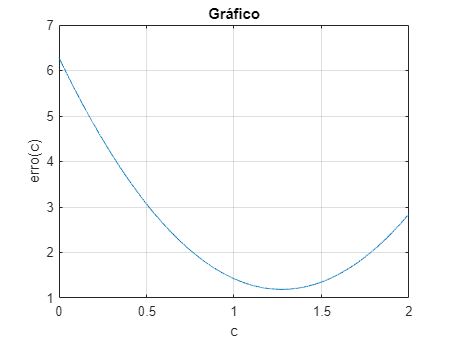

clc;
clear all;
close all;

syms t c g1 g2 t0 tp

erro1 = @(g1, c, t) (g1-sin(t).*c)^2;
erro2 = @(g2, c, t) (g2-sin(t).*c)^2;
res1= int(erro1,t,t0,t0+tp) + int(erro2,t,t0+tp,t0+2*tp);

g1 = 1;
g2 = -1;
t0 = 0;
tp = pi;
c = 0:0.0001:2;

erronum = eval(res1);
figure()                            

plot(c,erronum)    
xlabel('c')
ylabel('erro(c)')
grid
title('Gráfico')


D1 = @(g1, t) (g1.*sin(t));
D2 = @(g2, t) (g2.*sin(t));
res2 = eval(int(D1,t,t0,t0+tp) + int(D2,t,t0+tp,t0+2*tp));

d = @(t) (sin(t).^2);
res3 = int(d,t,t0,t0+2*tp);

Erro_min = res2/res3

$$Erro\_min = \frac{4}{\pi }$$